### Set up workspace 

clearvars
addpath('G:\My Drive\Matlab_work\BC\Irminger\colab-workspace\CTD_Processing')
addpath('G:\My Drive\Matlab_work\BC\Sea-Bird_Oxygen_Toolbox')
addpath('G:\My Drive\Matlab_work\BC\Sea-Bird-Toolbox')
addpath('G:\My Drive\Matlab_work\Functions\GSW')
addpath('C:\Users\fogaren\Desktop')
cd('G:\My Drive\Matlab_work\OSU\GeneralCode')
run('GeneralSettings.m')

% cast = alignCTD_KF(cast,CastString,a1,a2,a3) % Function
a1 = 4; a2 = 6; a3 = 8;
cd('G:\My Drive\Matlab_work\BC\Irminger\colab-workspace\CTD_Processing')

CTD_sen1 = 1; % Use primary or secondary CTD temp and sal
CTD_sen2 = 2; 


clear cast*
% Pick align_sec
a1 = 4;
align_sec = a1; 

### Use Bottle samples to calculate new SOC (gain) and E terms for CTD data 

% Create bottle summary file with CTD oxygen calculated using calibrated
% salinity product 
addpath('G:\Shared drives\NSF_Irminger\OOI Cruises CTD Casts\CTD_Data\Alfresco\Bottle_Files\Year3')
cd('G:\Shared drives\NSF_Irminger\OOI Cruises CTD Casts\CTD_Data\Alfresco\Year3')

btl = readtable('Irminger_Sea-03_AR7-01_Discrete_Summary_KF.xlsx','TextType','string');
btl.Winkler_mLL = double(btl.Winkler_mLL);
btl.Discrete_Salinity_psu = double(btl.Discrete_Salinity_psu);

btlsum05CTD1 = btl(btl.Cast == 5,:);
btlsum06CTD1 = btl(btl.Cast == 6,:);
btlsum07CTD1 = btl(btl.Cast == 7,:);
btlsum08CTD1 = btl(btl.Cast == 8,:);
btlsum09CTD1 = btl(btl.Cast == 9,:);
btlsum10CTD1 = btl(btl.Cast == 10,:);

btlsum05CTD1 = combine_btl_files_woutCTDcal('ar0701005.csv',btlsum05CTD1);

btlsum06CTD1 = combine_btl_files_woutCTDcal('ar0701006.csv',btlsum06CTD1);

btlsum07CTD1 = combine_btl_files_woutCTDcal('ar0701007.csv',btlsum07CTD1);

btlsum08CTD1 = combine_btl_files_woutCTDcal('ar0701008.csv',btlsum08CTD1);

btlsum09CTD1 = combine_btl_files_woutCTDcal('ar0701009.csv',btlsum09CTD1);

btlsum10CTD1 = combine_btl_files_woutCTDcal('ar0701010.csv',btlsum10CTD1);


btlsum05CTD2 = btl(btl.Cast == 5,:);
btlsum06CTD2 = btl(btl.Cast == 6,:);
btlsum07CTD2 = btl(btl.Cast == 7,:);
btlsum08CTD2 = btl(btl.Cast == 8,:);
btlsum09CTD2 = btl(btl.Cast == 9,:);
btlsum10CTD2 = btl(btl.Cast == 10,:);

btlsum05CTD2 = combine_btl_files_woutCTDcal('ar0701005.csv',btlsum05CTD2);

btlsum06CTD2 = combine_btl_files_woutCTDcal('ar0701006.csv',btlsum06CTD2);

btlsum07CTD2 = combine_btl_files_woutCTDcal('ar0701007.csv',btlsum07CTD2);

btlsum08CTD2 = combine_btl_files_woutCTDcal('ar0701008.csv',btlsum08CTD2);

btlsum09CTD2 = combine_btl_files_woutCTDcal('ar0701009.csv',btlsum09CTD2);

btlsum10CTD2 = combine_btl_files_woutCTDcal('ar0701010.csv',btlsum10CTD2);


btlsum_yr3 = [btlsum05CTD1; btlsum06CTD1; btlsum07CTD1; btlsum08CTD1; btlsum09CTD1; btlsum10CTD1];
btlsum0 = btlsum_yr3; %

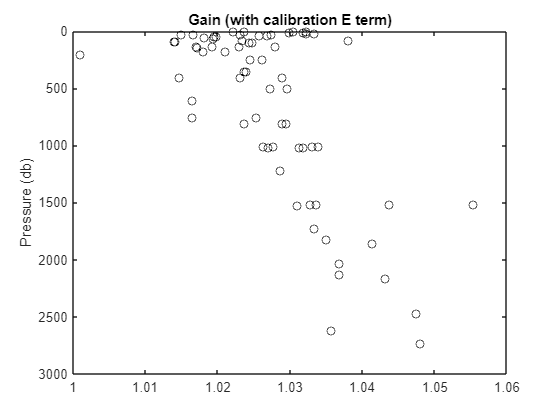

figure % Winkler/CTD Oxygen (without Leah calibrated Sal product)
plot(btlsum0.Winkler_mLL./btlsum0.CTDoxy_mLL,btlsum0.PrDM,'ok')
axis ij
ylabel('Pressure (db)')
title('Gain (with calibration E term)')

% Same oxgen sensor whole cruise  
% Calibration standards from SBE xmlcon file 

cal.SOC = double(3.79510e-001);
cal.VOFFSET = double(-5.82400e-001);
cal.A = double(-4.14790e-003);
cal.B = double(2.08070e-004);
cal.C = double(-3.05950e-006);
cal.E = double(3.60000e-002);
cal.Tau20 = double(1.16000e+000);
cal.INSTRUMENT_TYPE = 'SBE43';
cal.SERIALNO = '0338';
cal.OCALDATE = '16-Jan-16';

H = [-0.033, 5000, 1450]; % Default 

cal1 = cal;
cal2 = cal;

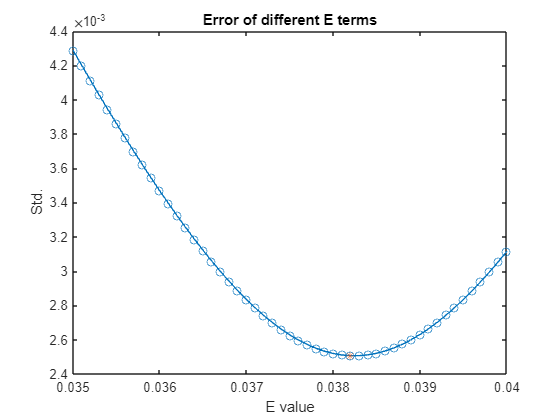

cal.E2 = 0.0382


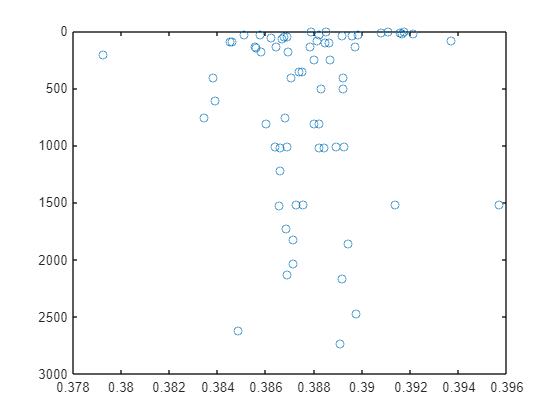

cd('G:\My Drive\Matlab_work\BC\Irminger\colab-workspace\CTD_Processing')

btlsum0.CTDoxy_mLL_cal = btlsum0.CTDoxy_mLL; % Because don't have cal product

[cal1] = E2_calculation(btlsum0,cal1,CTD_sen1); % Use dummy bottle summary with outlier removed

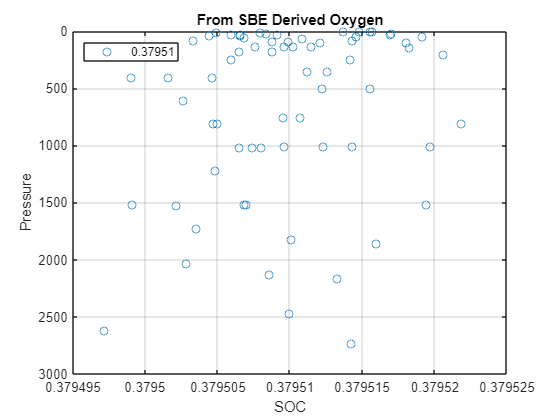

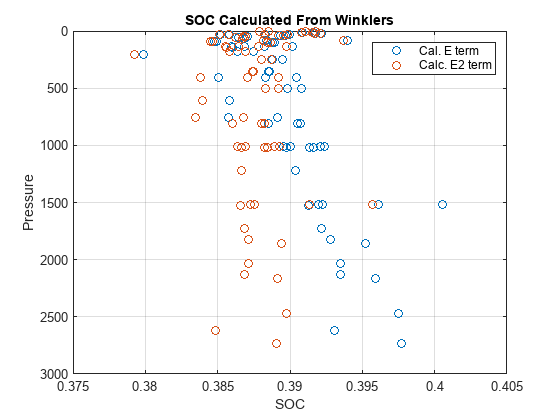

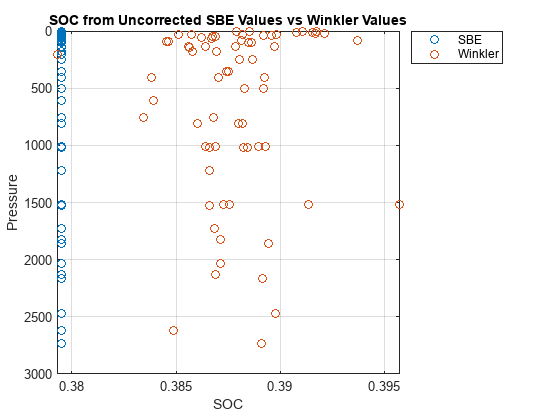

New SOC = 0.38784
EGain = 1.0219+/- 0.0066052



[cal1] = Gain_E2_Calculation(btlsum0,cal1,CTD_sen1); % Use dummy bottle summary with any outliers removed

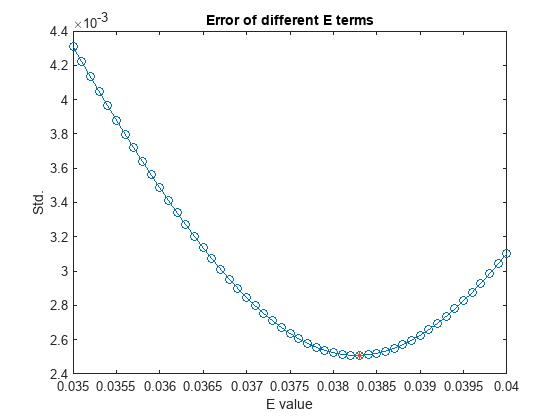

cal.E2 = 0.0383


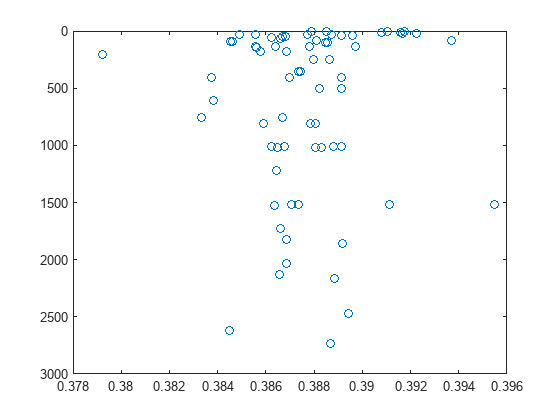


[cal2] = E2_calculation(btlsum0,cal2,CTD_sen2); % Use dummy bottle summary with outlier removed

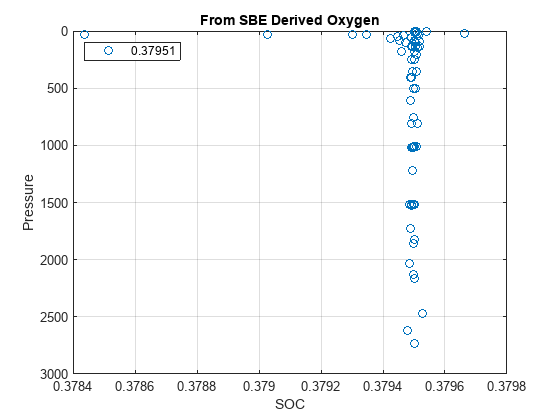

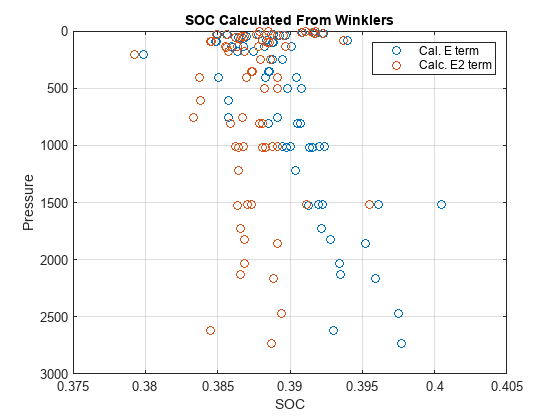

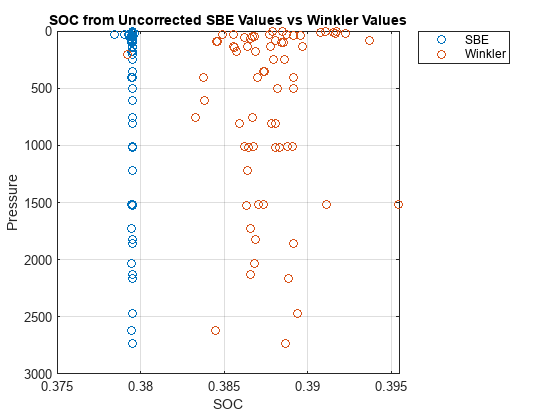

New SOC = 0.38771
EGain = 1.0216+/- 0.0066098



[cal2] = Gain_E2_Calculation(btlsum0,cal2,CTD_sen2); % Use dummy bottle summary with any outliers removed

% Read in processed casts
% Processed with 4 sec DO alignment and SBE cal hysteresis, SOC, and E term
% 
cd('G:\Shared drives\NSF_Irminger\OOI Cruises CTD Casts\CTD_Data\Alfresco\Year3')
cast01uCTD1 = readSBScnv( 'uar0701001.cnv' );
cast02uCTD1 = readSBScnv( 'uar0701002.cnv' );
cast03uCTD1 = readSBScnv( 'uar0701003.cnv' );
cast04uCTD1 = readSBScnv( 'uar0701004.cnv' );
cast05uCTD1 = readSBScnv( 'uar0701005.cnv' );
cast06uCTD1 = readSBScnv( 'uar0701006.cnv' );
cast07uCTD1 = readSBScnv( 'uar0701007.cnv' );
cast08uCTD1 = readSBScnv( 'uar0701008.cnv' );
cast09uCTD1 = readSBScnv( 'uar0701009.cnv' );
cast10uCTD1 = readSBScnv( 'uar0701010.cnv' );

cast01dCTD1 = readSBScnv( 'dar0701001.cnv' );
cast02dCTD1 = readSBScnv( 'dar0701002.cnv' );
cast03dCTD1 = readSBScnv( 'dar0701003.cnv' );
cast04dCTD1 = readSBScnv( 'dar0701004.cnv' );
cast05dCTD1 = readSBScnv( 'dar0701005.cnv' );
cast06dCTD1 = readSBScnv( 'dar0701006.cnv' );
cast07dCTD1 = readSBScnv( 'dar0701007.cnv' );
cast08dCTD1 = readSBScnv( 'dar0701008.cnv' );
cast09dCTD1 = readSBScnv( 'dar0701009.cnv' );
cast10dCTD1 = readSBScnv( 'dar0701010.cnv' );

cast01uCTD2 = readSBScnv( 'uar0701001.cnv' );
cast02uCTD2 = readSBScnv( 'uar0701002.cnv' );
cast03uCTD2 = readSBScnv( 'uar0701003.cnv' );
cast04uCTD2 = readSBScnv( 'uar0701004.cnv' );
cast05uCTD2 = readSBScnv( 'uar0701005.cnv' );
cast06uCTD2 = readSBScnv( 'uar0701006.cnv' );
cast07uCTD2 = readSBScnv( 'uar0701007.cnv' );
cast08uCTD2 = readSBScnv( 'uar0701008.cnv' );
cast09uCTD2 = readSBScnv( 'uar0701009.cnv' );
cast10uCTD2 = readSBScnv( 'uar0701010.cnv' );

cast01dCTD2 = readSBScnv( 'dar0701001.cnv' );
cast02dCTD2 = readSBScnv( 'dar0701002.cnv' );
cast03dCTD2 = readSBScnv( 'dar0701003.cnv' );
cast04dCTD2 = readSBScnv( 'dar0701004.cnv' );
cast05dCTD2 = readSBScnv( 'dar0701005.cnv' );
cast06dCTD2 = readSBScnv( 'dar0701006.cnv' );
cast07dCTD2 = readSBScnv( 'dar0701007.cnv' );
cast08dCTD2 = readSBScnv( 'dar0701008.cnv' );
cast09dCTD2 = readSBScnv( 'dar0701009.cnv' );
cast10dCTD2 = readSBScnv( 'dar0701010.cnv' );


% Format to table without Leah's product 
[cast01uCTD1, ~] = combine_CTD_files_woutCTDcal(cast01uCTD1); [cast01dCTD1, ~] = combine_CTD_files_woutCTDcal(cast01dCTD1);  
[cast02uCTD1, ~] = combine_CTD_files_woutCTDcal(cast02uCTD1); [cast02dCTD1, ~] = combine_CTD_files_woutCTDcal(cast02dCTD1);  
[cast03uCTD1, ~] = combine_CTD_files_woutCTDcal(cast03uCTD1); [cast03dCTD1, ~] = combine_CTD_files_woutCTDcal(cast03dCTD1);  
[cast04uCTD1, ~] = combine_CTD_files_woutCTDcal(cast04uCTD1); [cast04dCTD1, ~] = combine_CTD_files_woutCTDcal(cast04dCTD1);  
[cast05uCTD1, ~] = combine_CTD_files_woutCTDcal(cast05uCTD1); [cast05dCTD1, ~] = combine_CTD_files_woutCTDcal(cast05dCTD1);  
[cast06uCTD1, ~] = combine_CTD_files_woutCTDcal(cast06uCTD1); [cast06dCTD1, ~] = combine_CTD_files_woutCTDcal(cast06dCTD1);  
[cast07uCTD1, ~] = combine_CTD_files_woutCTDcal(cast07uCTD1); [cast07dCTD1, ~] = combine_CTD_files_woutCTDcal(cast07dCTD1);  
[cast08uCTD1, ~] = combine_CTD_files_woutCTDcal(cast08uCTD1); [cast08dCTD1, ~] = combine_CTD_files_woutCTDcal(cast08dCTD1);  
[cast09uCTD1, ~] = combine_CTD_files_woutCTDcal(cast09uCTD1); [cast09dCTD1, ~] = combine_CTD_files_woutCTDcal(cast09dCTD1);  
[cast10uCTD1, ~] = combine_CTD_files_woutCTDcal(cast10uCTD1); [cast10dCTD1, ~] = combine_CTD_files_woutCTDcal(cast10dCTD1); 

[cast01uCTD2, ~] = combine_CTD_files_woutCTDcal(cast01uCTD2); [cast01dCTD2, ~] = combine_CTD_files_woutCTDcal(cast01dCTD2);  
[cast02uCTD2, ~] = combine_CTD_files_woutCTDcal(cast02uCTD2); [cast02dCTD2, ~] = combine_CTD_files_woutCTDcal(cast02dCTD2);  
[cast03uCTD2, ~] = combine_CTD_files_woutCTDcal(cast03uCTD2); [cast03dCTD2, ~] = combine_CTD_files_woutCTDcal(cast03dCTD2);  
[cast04uCTD2, ~] = combine_CTD_files_woutCTDcal(cast04uCTD2); [cast04dCTD2, ~] = combine_CTD_files_woutCTDcal(cast04dCTD2);  
[cast05uCTD2, ~] = combine_CTD_files_woutCTDcal(cast05uCTD2); [cast05dCTD2, ~] = combine_CTD_files_woutCTDcal(cast05dCTD2);  
[cast06uCTD2, ~] = combine_CTD_files_woutCTDcal(cast06uCTD2); [cast06dCTD2, ~] = combine_CTD_files_woutCTDcal(cast06dCTD2);  
[cast07uCTD2, ~] = combine_CTD_files_woutCTDcal(cast07uCTD2); [cast07dCTD2, ~] = combine_CTD_files_woutCTDcal(cast07dCTD2);  
[cast08uCTD2, ~] = combine_CTD_files_woutCTDcal(cast08uCTD2); [cast08dCTD2, ~] = combine_CTD_files_woutCTDcal(cast08dCTD2);  
[cast09uCTD2, ~] = combine_CTD_files_woutCTDcal(cast09uCTD2); [cast09dCTD2, ~] = combine_CTD_files_woutCTDcal(cast09dCTD2);  
[cast10uCTD2, ~] = combine_CTD_files_woutCTDcal(cast10uCTD2); [cast10dCTD2, ~] = combine_CTD_files_woutCTDcal(cast10dCTD2); 


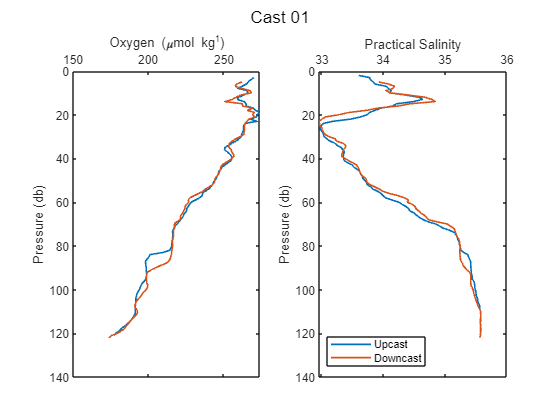

% Using function written for missing final Sal product 
sal_plots = 1; leah_plot = 0; 
% [castu, castd, btlsum] = Process_Cast_Gain_E2_woutCTDcal(castu,castd,cal,btlsum,sal_plots,leah_plots,CTD_sen,CastString)

[cast01uCTD1, cast01dCTD1, btlsum01CTD1] = Process_Cast_Gain_E2_woutCTDcal(cast01uCTD1,cast01dCTD1,cal1,0,sal_plots,leah_plot,CTD_sen1,'Cast 01');

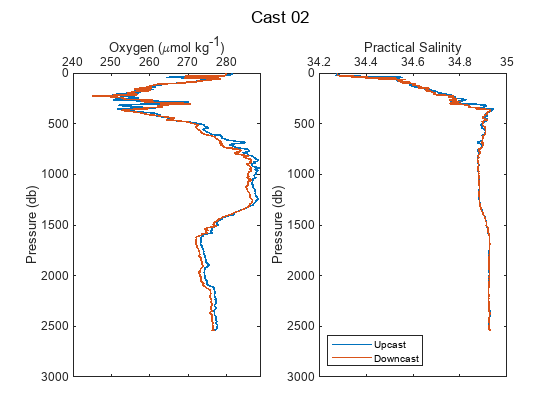

[cast02uCTD1, cast02dCTD1, btlsum02CTD1] = Process_Cast_Gain_E2_woutCTDcal(cast02uCTD1,cast02dCTD1,cal1,0,sal_plots,leah_plot,CTD_sen1,'Cast 02');

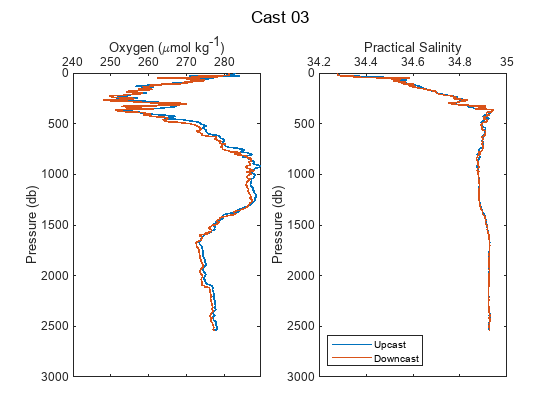

[cast03uCTD1, cast03dCTD1, btlsum03CTD1] = Process_Cast_Gain_E2_woutCTDcal(cast03uCTD1,cast03dCTD1,cal1,0,sal_plots,leah_plot,CTD_sen1,'Cast 03');

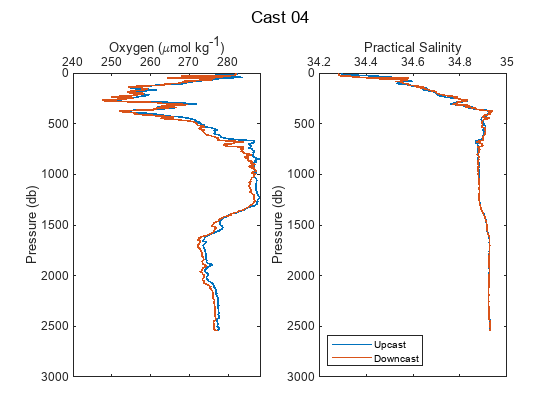

[cast04uCTD1, cast04dCTD1, btlsum04CTD1] = Process_Cast_Gain_E2_woutCTDcal(cast04uCTD1,cast04dCTD1,cal1,0,sal_plots,leah_plot,CTD_sen1,'Cast 04');

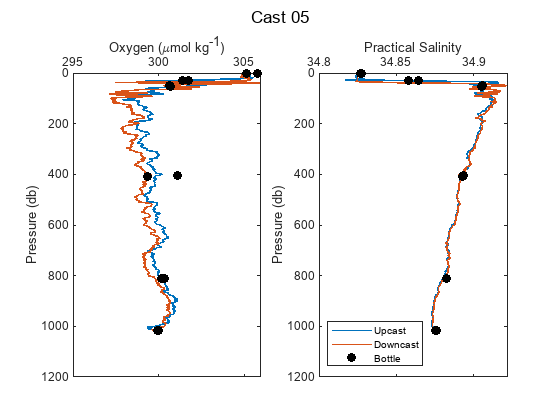

[cast05uCTD1, cast05dCTD1, btlsum05CTD1] = Process_Cast_Gain_E2_woutCTDcal(cast05uCTD1,cast05dCTD1,cal1,btlsum05CTD1,sal_plots,leah_plot,CTD_sen1,'Cast 05');

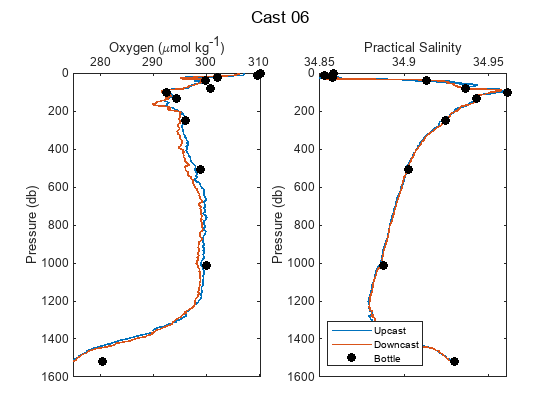

[cast06uCTD1, cast06dCTD1, btlsum06CTD1] = Process_Cast_Gain_E2_woutCTDcal(cast06uCTD1,cast06dCTD1,cal1,btlsum06CTD1,sal_plots,leah_plot,CTD_sen1,'Cast 06');

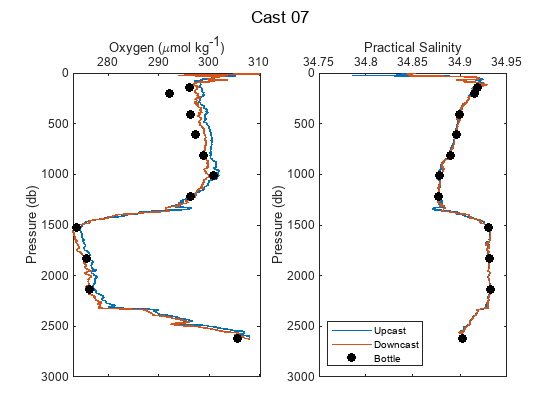

[cast07uCTD1, cast07dCTD1, btlsum07CTD1] = Process_Cast_Gain_E2_woutCTDcal(cast07uCTD1,cast07dCTD1,cal1,btlsum07CTD1,sal_plots,leah_plot,CTD_sen1,'Cast 07');

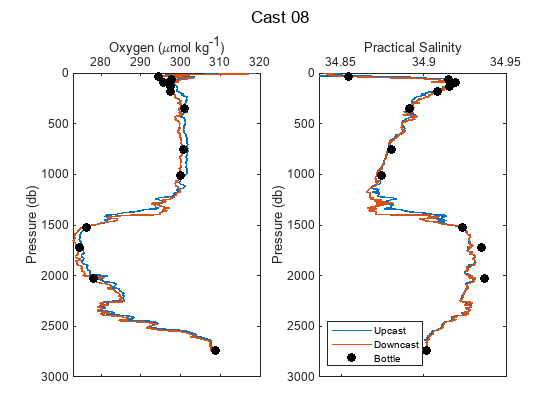

[cast08uCTD1, cast08dCTD1, btlsum08CTD1] = Process_Cast_Gain_E2_woutCTDcal(cast08uCTD1,cast08dCTD1,cal1,btlsum08CTD1,sal_plots,leah_plot,CTD_sen1,'Cast 08');

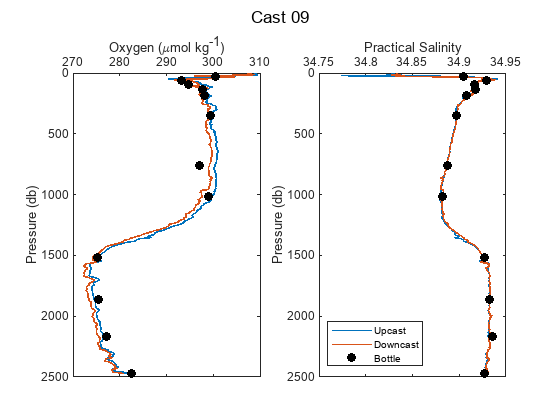

[cast09uCTD1, cast09dCTD1, btlsum09CTD1] = Process_Cast_Gain_E2_woutCTDcal(cast09uCTD1,cast09dCTD1,cal1,btlsum09CTD1,sal_plots,leah_plot,CTD_sen1,'Cast 09');

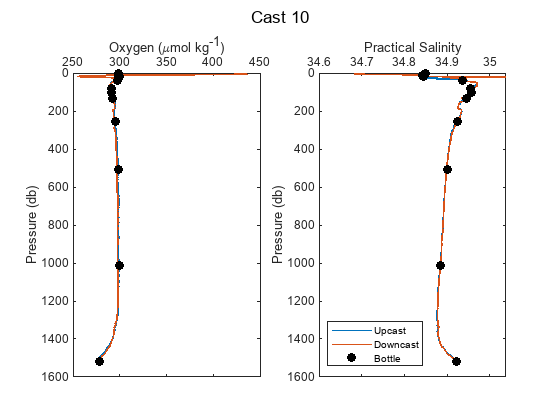

[cast10uCTD1, cast10dCTD1, btlsum10CTD1] = Process_Cast_Gain_E2_woutCTDcal(cast10uCTD1,cast10dCTD1,cal1,btlsum10CTD1,sal_plots,leah_plot,CTD_sen1,'Cast 10');

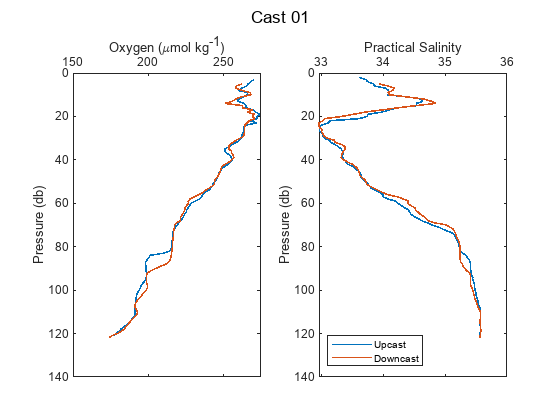


[cast01uCTD2, cast01dCTD2, btlsum01CTD2] = Process_Cast_Gain_E2_woutCTDcal(cast01uCTD2,cast01dCTD2,cal2,0,sal_plots,leah_plot,CTD_sen2,'Cast 01');

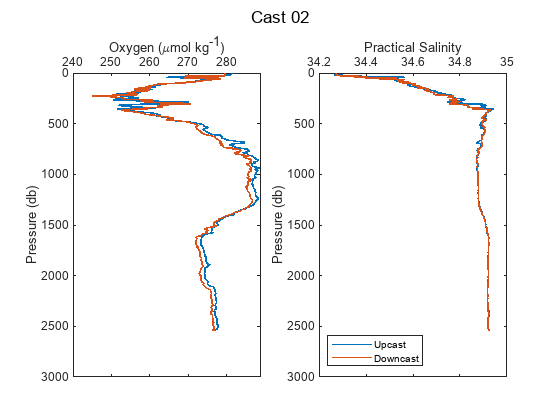

[cast02uCTD2, cast02dCTD2, btlsum02CTD2] = Process_Cast_Gain_E2_woutCTDcal(cast02uCTD2,cast02dCTD2,cal2,0,sal_plots,leah_plot,CTD_sen2,'Cast 02');

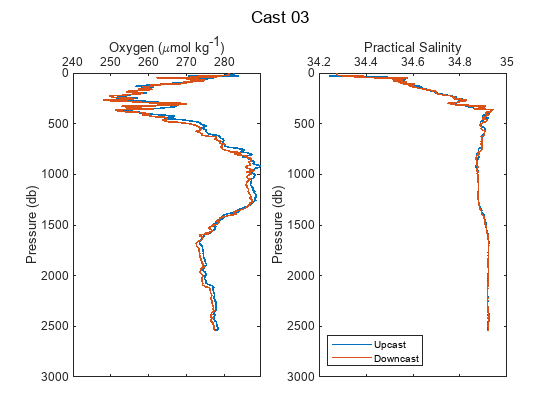

[cast03uCTD2, cast03dCTD2, btlsum03CTD2] = Process_Cast_Gain_E2_woutCTDcal(cast03uCTD2,cast03dCTD2,cal2,0,sal_plots,leah_plot,CTD_sen2,'Cast 03');

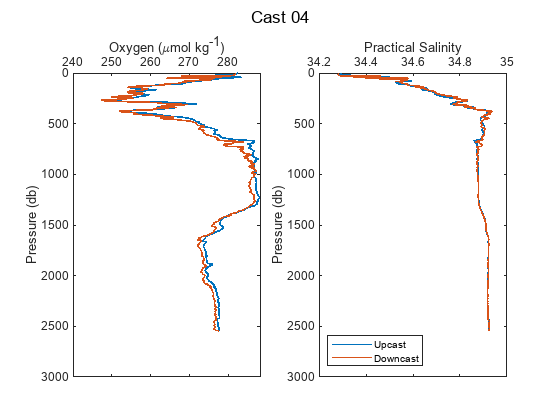

[cast04uCTD2, cast04dCTD2, btlsum04CTD2] = Process_Cast_Gain_E2_woutCTDcal(cast04uCTD2,cast04dCTD2,cal2,0,sal_plots,leah_plot,CTD_sen2,'Cast 04');

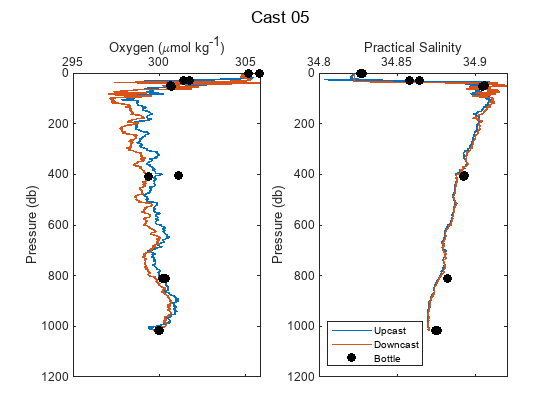

[cast05uCTD2, cast05dCTD2, btlsum05CTD2] = Process_Cast_Gain_E2_woutCTDcal(cast05uCTD2,cast05dCTD2,cal2,btlsum05CTD2,sal_plots,leah_plot,CTD_sen2,'Cast 05');

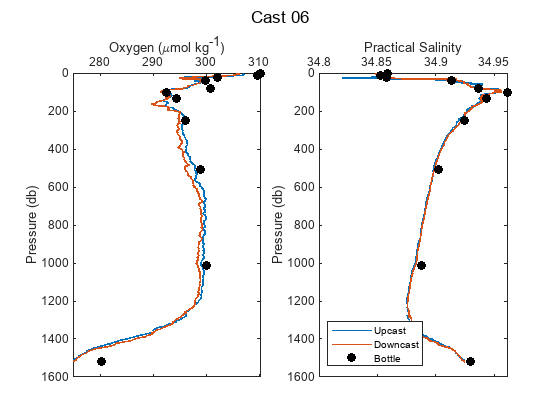

[cast06uCTD2, cast06dCTD2, btlsum06CTD2] = Process_Cast_Gain_E2_woutCTDcal(cast06uCTD2,cast06dCTD2,cal2,btlsum06CTD2,sal_plots,leah_plot,CTD_sen2,'Cast 06');

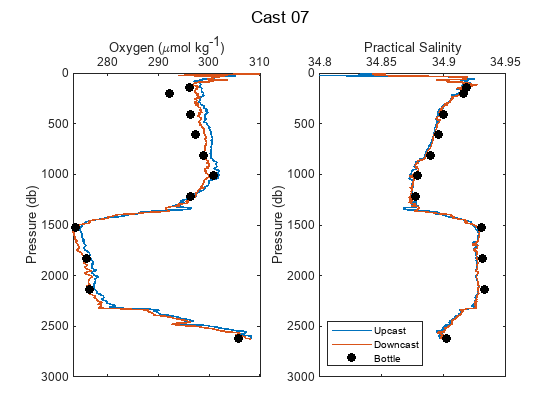

[cast07uCTD2, cast07dCTD2, btlsum07CTD2] = Process_Cast_Gain_E2_woutCTDcal(cast07uCTD2,cast07dCTD2,cal2,btlsum07CTD2,sal_plots,leah_plot,CTD_sen2,'Cast 07');

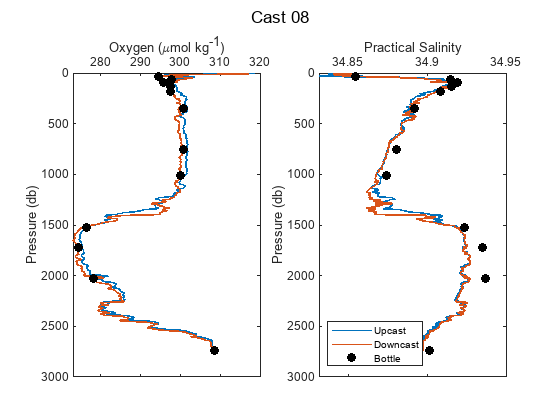

[cast08uCTD2, cast08dCTD2, btlsum08CTD2] = Process_Cast_Gain_E2_woutCTDcal(cast08uCTD2,cast08dCTD2,cal2,btlsum08CTD2,sal_plots,leah_plot,CTD_sen2,'Cast 08');

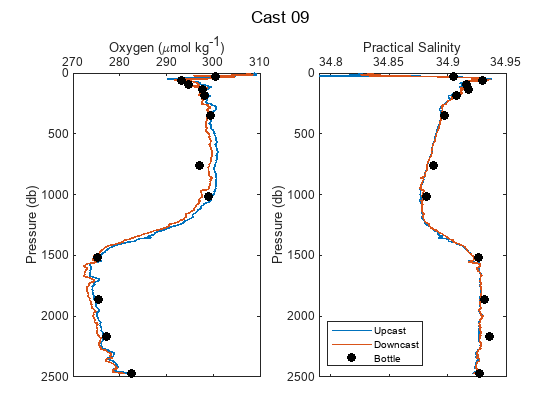

[cast09uCTD2, cast09dCTD2, btlsum09CTD2] = Process_Cast_Gain_E2_woutCTDcal(cast09uCTD2,cast09dCTD2,cal2,btlsum09CTD2,sal_plots,leah_plot,CTD_sen2,'Cast 09');

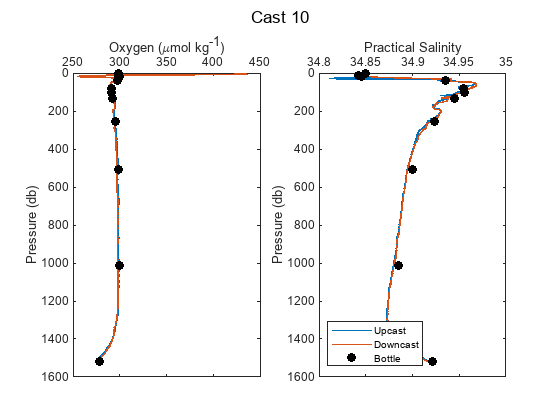

[cast10uCTD2, cast10dCTD2, btlsum10CTD2] = Process_Cast_Gain_E2_woutCTDcal(cast10uCTD2,cast10dCTD2,cal2,btlsum10CTD2,sal_plots,leah_plot,CTD_sen2,'Cast 10');

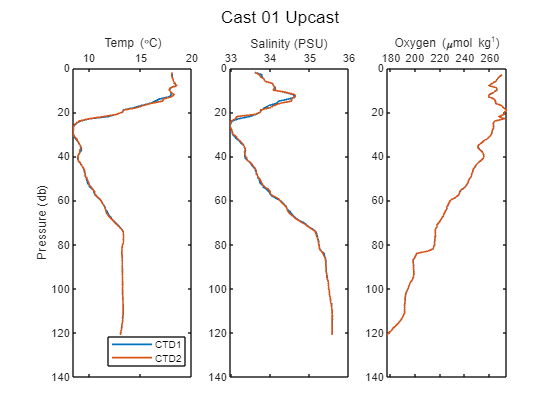

DO1 - DO2 = 0.074475 +/- 0.016784 umol/kg
Sal1 - Sal2 = 0.022415 +/- 0.051131 PSU


[DOdiff01u, DOstd01] = CTD1vsCTD2(cast01uCTD1,cast01uCTD2,btlsum01CTD1,'Cast 01 Upcast');

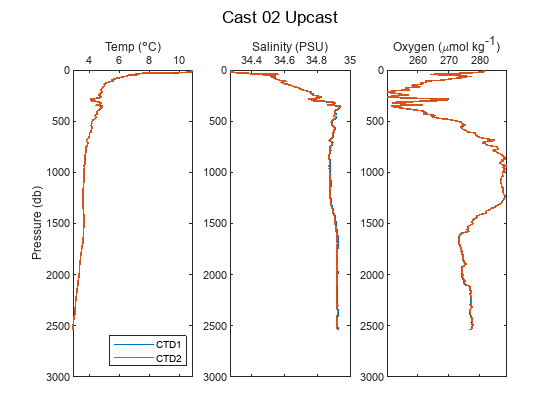

DO1 - DO2 = 0.067348 +/- 0.072634 umol/kg
Sal1 - Sal2 = 0.0040339 +/- 0.0036792 PSU


[DOdiff02u, DOstd02] = CTD1vsCTD2(cast02uCTD1,cast02uCTD2,btlsum02CTD1,'Cast 02 Upcast');

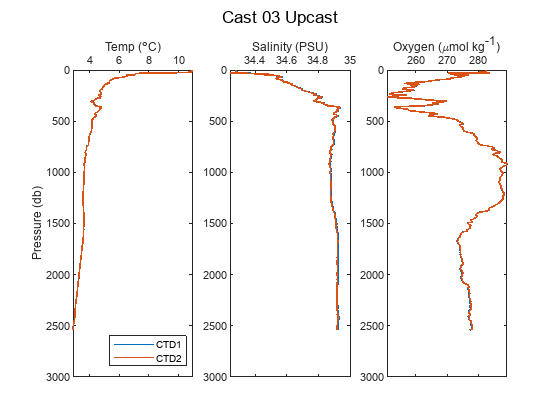

DO1 - DO2 = 0.067406 +/- 0.072676 umol/kg
Sal1 - Sal2 = 0.0039636 +/- 0.0037052 PSU


[DOdiff03u, DOstd03] = CTD1vsCTD2(cast03uCTD1,cast03uCTD2,btlsum03CTD1,'Cast 03 Upcast');

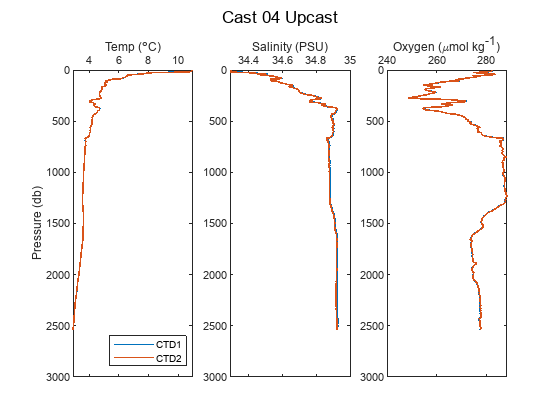

DO1 - DO2 = 0.067502 +/- 0.0728 umol/kg
Sal1 - Sal2 = 0.0039665 +/- 0.003089 PSU


[DOdiff04u, DOstd04] = CTD1vsCTD2(cast04uCTD1,cast04uCTD2,btlsum04CTD1,'Cast 04 Upcast');

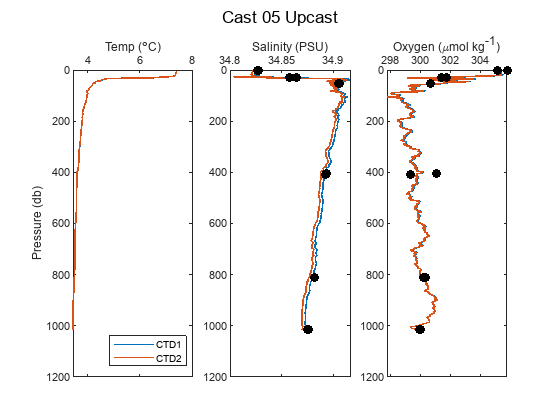

DO1 - DO2 = 0.047787 +/- 0.031793 umol/kg
Sal1 - Sal2 = 0.0031939 +/- 0.0015319 PSU


[DOdiff05u, DOstd05] = CTD1vsCTD2(cast05uCTD1,cast05uCTD2,btlsum05CTD1,'Cast 05 Upcast');

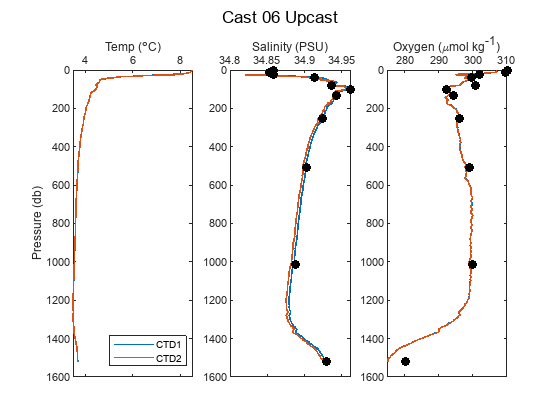

DO1 - DO2 = 0.042767 +/- 0.046482 umol/kg
Sal1 - Sal2 = 0.0035078 +/- 0.0013699 PSU


[DOdiff06u, DOstd06] = CTD1vsCTD2(cast06uCTD1,cast06uCTD2,btlsum06CTD1,'Cast 06 Upcast');

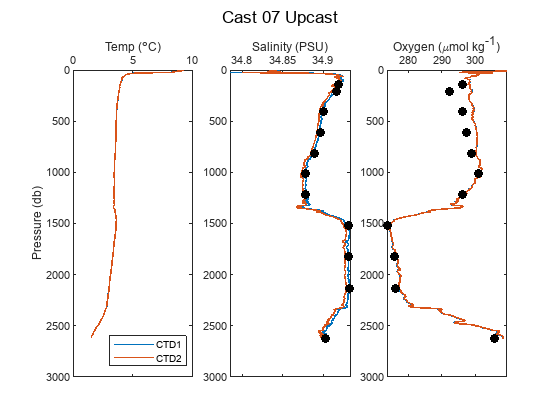

DO1 - DO2 = 0.074126 +/- 0.080237 umol/kg
Sal1 - Sal2 = 0.0037661 +/- 0.001414 PSU


[DOdiff07u, DOstd07] = CTD1vsCTD2(cast07uCTD1,cast07uCTD2,btlsum07CTD1,'Cast 07 Upcast');

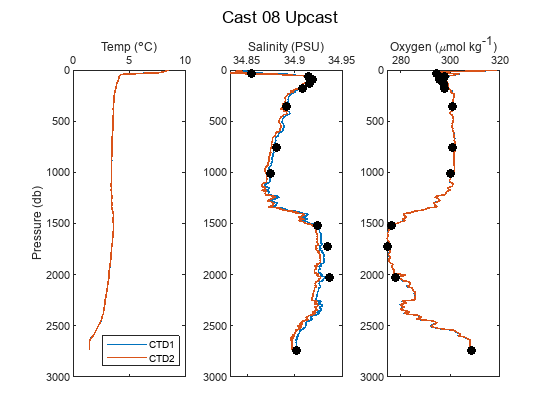

DO1 - DO2 = 0.079143 +/- 0.084458 umol/kg
Sal1 - Sal2 = 0.0039162 +/- 0.0012549 PSU


[DOdiff08u, DOstd08] = CTD1vsCTD2(cast08uCTD1,cast08uCTD2,btlsum08CTD1,'Cast 08 Upcast');

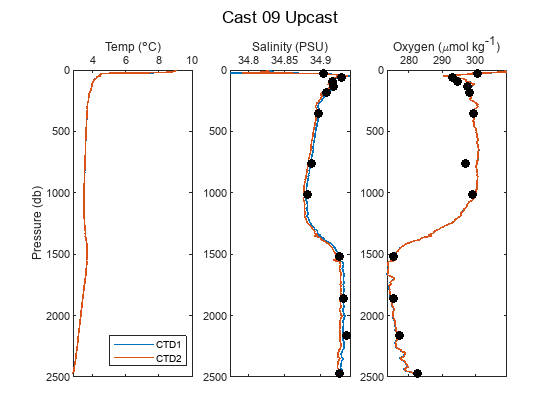

DO1 - DO2 = 0.067016 +/- 0.073457 umol/kg
Sal1 - Sal2 = 0.0038517 +/- 0.0023567 PSU


[DOdiff09u, DOstd09] = CTD1vsCTD2(cast09uCTD1,cast09uCTD2,btlsum09CTD1,'Cast 09 Upcast');

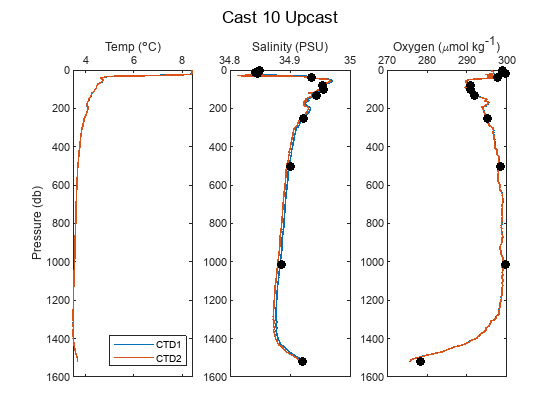

DO1 - DO2 = 0.042807 +/- 0.046564 umol/kg
Sal1 - Sal2 = 0.0039129 +/- 0.0024947 PSU


[DOdiff10u, DOstd10] = CTD1vsCTD2(cast10uCTD1,cast10uCTD2,btlsum10CTD1,'Cast 10 Upcast');

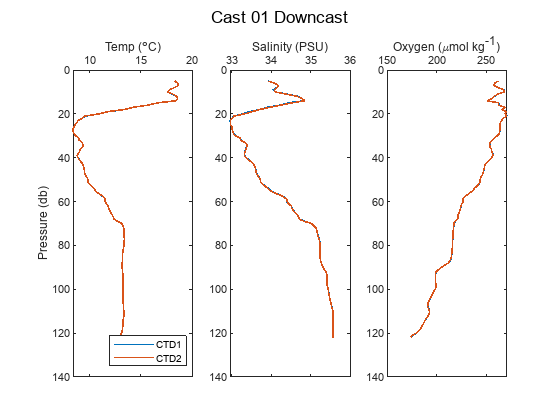

DO1 - DO2 = 0.073559 +/- 0.012918 umol/kg
Sal1 - Sal2 = 0.0080513 +/- 0.017385 PSU



[DOdiff01d, DOstd01] = CTD1vsCTD2(cast01dCTD1,cast01dCTD2,btlsum01CTD1,'Cast 01 Downcast');

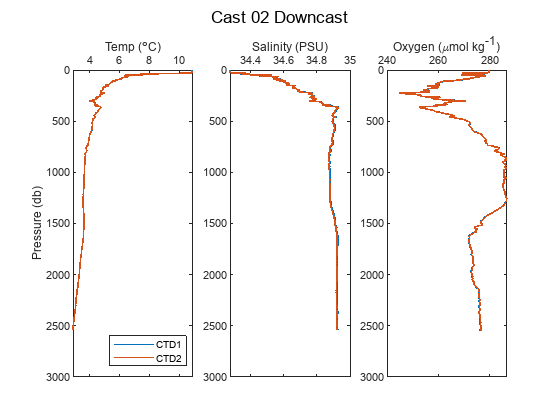

DO1 - DO2 = 0.067214 +/- 0.072476 umol/kg
Sal1 - Sal2 = 0.0038965 +/- 0.0027572 PSU


[DOdiff02d, DOstd02] = CTD1vsCTD2(cast02dCTD1,cast02dCTD2,btlsum02CTD1,'Cast 02 Downcast');

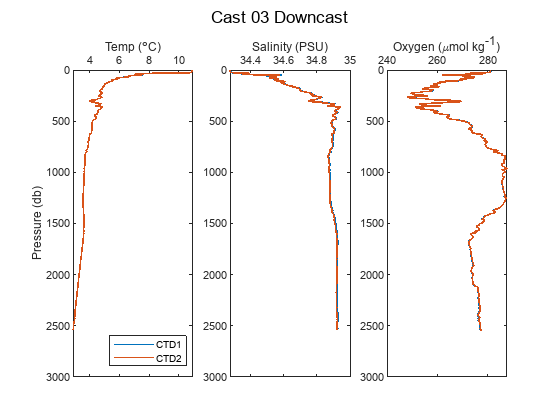

DO1 - DO2 = 0.067319 +/- 0.07263 umol/kg
Sal1 - Sal2 = 0.0038442 +/- 0.0033813 PSU


[DOdiff03d, DOstd03] = CTD1vsCTD2(cast03dCTD1,cast03dCTD2,btlsum03CTD1,'Cast 03 Downcast');

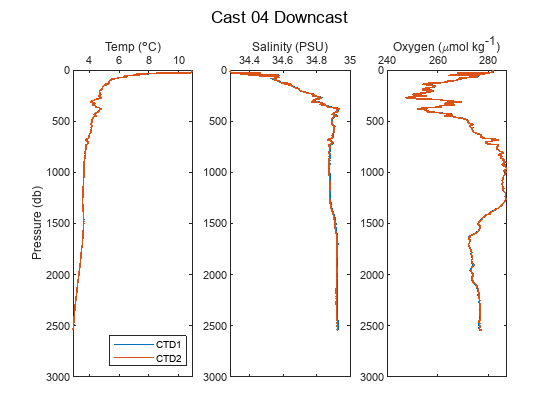

DO1 - DO2 = 0.06732 +/- 0.0726 umol/kg
Sal1 - Sal2 = 0.0036434 +/- 0.0040138 PSU


[DOdiff04d, DOstd04] = CTD1vsCTD2(cast04dCTD1,cast04dCTD2,btlsum04CTD1,'Cast 04 Downcast');

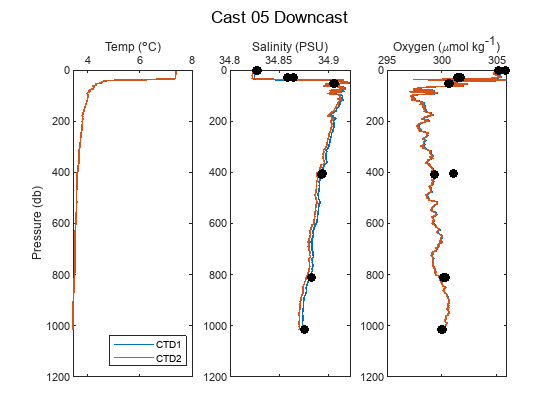

DO1 - DO2 = 0.04764 +/- 0.031849 umol/kg
Sal1 - Sal2 = 0.0028942 +/- 0.0023527 PSU


[DOdiff05d, DOstd05] = CTD1vsCTD2(cast05dCTD1,cast05dCTD2,btlsum05CTD1,'Cast 05 Downcast');

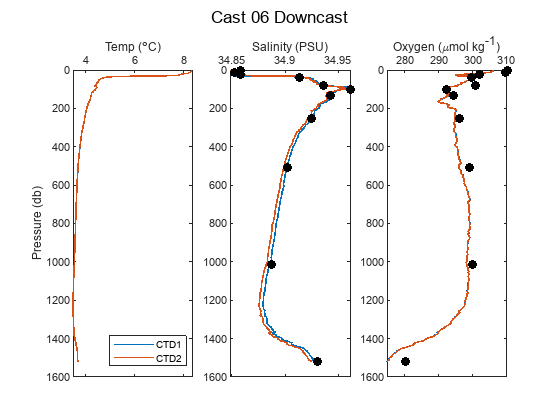

DO1 - DO2 = 0.042725 +/- 0.04653 umol/kg
Sal1 - Sal2 = 0.0032734 +/- 0.0017467 PSU


[DOdiff06d, DOstd06] = CTD1vsCTD2(cast06dCTD1,cast06dCTD2,btlsum06CTD1,'Cast 06 Downcast');

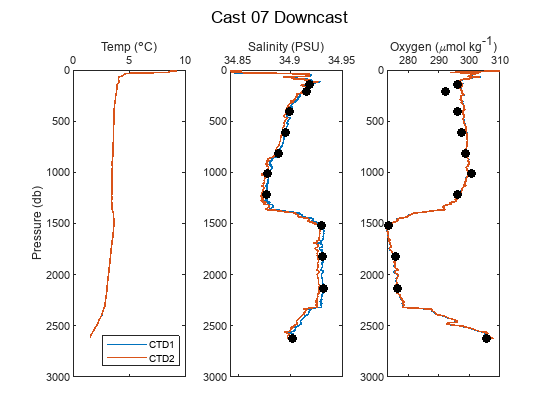

DO1 - DO2 = 0.07383 +/- 0.079833 umol/kg
Sal1 - Sal2 = 0.0035863 +/- 0.0011934 PSU


[DOdiff07d, DOstd07] = CTD1vsCTD2(cast07dCTD1,cast07dCTD2,btlsum07CTD1,'Cast 07 Downcast');

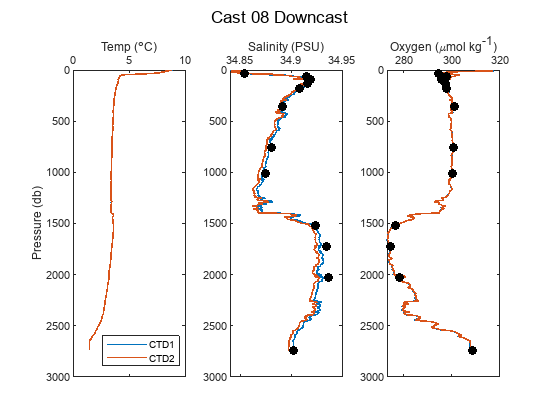

DO1 - DO2 = 0.078942 +/- 0.084158 umol/kg
Sal1 - Sal2 = 0.0036984 +/- 0.00115 PSU


[DOdiff08d, DOstd08] = CTD1vsCTD2(cast08dCTD1,cast08dCTD2,btlsum08CTD1,'Cast 08 Downcast');

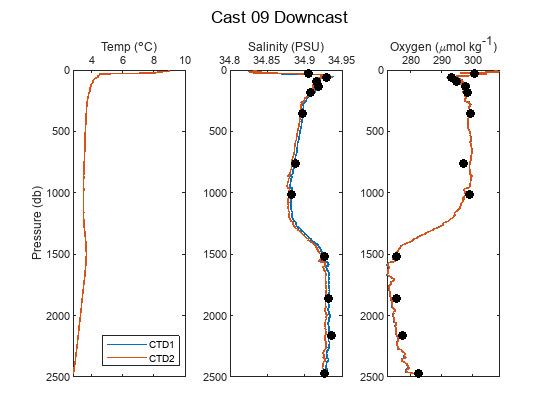

DO1 - DO2 = 0.066823 +/- 0.073213 umol/kg
Sal1 - Sal2 = 0.0037835 +/- 0.0014295 PSU


[DOdiff09d, DOstd09] = CTD1vsCTD2(cast09dCTD1,cast09dCTD2,btlsum09CTD1,'Cast 09 Downcast');

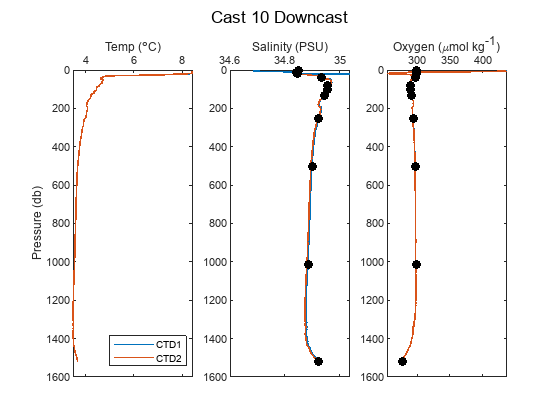

DO1 - DO2 = 0.042835 +/- 0.047044 umol/kg
Sal1 - Sal2 = 0.0043144 +/- 0.0098576 PSU


[DOdiff10d, DOstd10] = CTD1vsCTD2(cast10dCTD1,cast10dCTD2,btlsum10CTD1,'Cast 10 Downcast');



DOdiff = [DOdiff01u DOdiff02u DOdiff03u DOdiff04u DOdiff05u DOdiff06u...
    DOdiff07u DOdiff08u DOdiff09u DOdiff10u...
    DOdiff01d DOdiff02d DOdiff03d DOdiff04d DOdiff05d DOdiff06d...
    DOdiff07d DOdiff08d DOdiff09d DOdiff10d];
nanmean(abs(DOdiff))

ans = 0.0629

nanstd(DOdiff)

ans = 0.0131

% cd('G:\Shared drives\NSF_Irminger\OOI Cruises CTD Casts\CTD_Data\Alfresco\Year3')
% dt_Processed = datetime;
% save Year3_CTD1vsCTD2_KF cast* dt_Processed %%

function [DOdiff, DOstd] = CTD1vsCTD2(castCTD1,castCTD2,btlsumCTD,CastString)

    figure
    subplot(1,3,1)
    plot(castCTD1.temp1,castCTD1.prs,'Linewidth',1.2)
    hold on
    plot(castCTD2.temp2,castCTD2.prs,'Linewidth',1.2)
    axis ij
    ylabel('Pressure (db)')
    xlabel('Temp (\circC)')
    ax = gca;
    ax.XAxisLocation = 'top';
    legend('CTD1','CTD2','Location','SE')

    subplot(1,3,2)
    plot(castCTD1.sal1,castCTD1.prs,'Linewidth',1.2)
    hold on
    plot(castCTD2.sal2,castCTD2.prs,'Linewidth',1.2)
    if height(btlsumCTD) ~= 1
        plot(btlsumCTD.Discrete_Salinity_psu,btlsumCTD.prs,'ok','MarkerFaceColor','k')
    end
    axis ij
    xlabel('Salinity (PSU)')
    ax = gca;
    ax.XAxisLocation = 'top';
    
    subplot(1,3,3)
    plot(castCTD1.DOcorr_umolkg,castCTD1.prs,'Linewidth',1.2)
    hold on
    plot(castCTD2.DOcorr_umolkg,castCTD2.prs,'Linewidth',1.2)
    if height(btlsumCTD) ~= 1
        plot(btlsumCTD.Winkler_umolkg,btlsumCTD.prs,'ok','MarkerFaceColor','k')
    end
    axis ij
    xlabel('Oxygen (\mumol kg^-^1)')
    ax = gca;
    ax.XAxisLocation = 'top';
    sgtitle(CastString)

    DOdiff = nanmean(abs(castCTD1.DOcorr_umolkg-castCTD2.DOcorr_umolkg));
    DOstd = nanstd(castCTD1.DOcorr_umolkg-castCTD2.DOcorr_umolkg);
    disp(['DO1 - DO2 = ' num2str(DOdiff) ' +/- ' num2str(DOstd) ' umol/kg'])

    Saldiff = nanmean(abs(castCTD1.sal1-castCTD2.sal2));
    Salstd = nanstd(castCTD1.sal1-castCTD2.sal2);
    disp(['Sal1 - Sal2 = ' num2str(Saldiff) ' +/- ' num2str(Salstd) ' PSU'])

end